Promentilla, Jose Mikhael Uriel

Dela Torre, Alexczar

# DSP MP3

## Digital Image Structure

### RGB Color Channels and Grayscaling

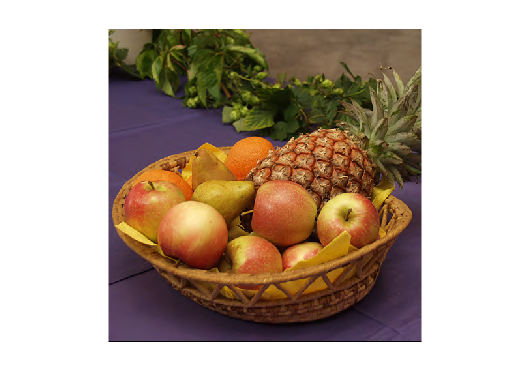

% read and display image
img = imread('fruits_rgb.bmp');
figure('Name','Figure 1: Original Image','NumberTitle','off');
imshow(img);

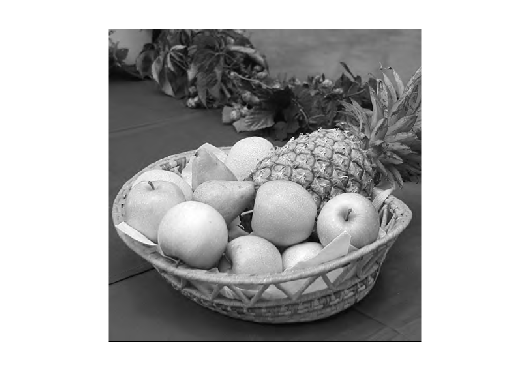


% Image into rgb color planes
[R,G,B] = imsplit(img);
figure('Name','Figure 2: Red Channel','NumberTitle','off');
colormap(gray);
imshow(R);

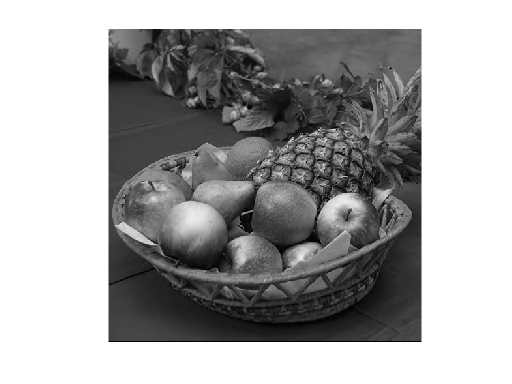

figure('Name','Figure 3: Green Channel','NumberTitle','off');
colormap(gray);
imshow(G);

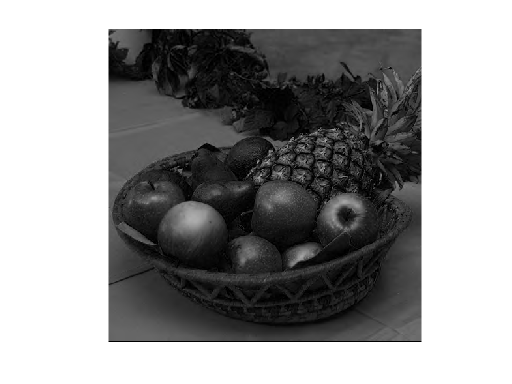

figure('Name','Figure 4: Blue Channel','NumberTitle','off');
colormap(gray);
imshow(B);

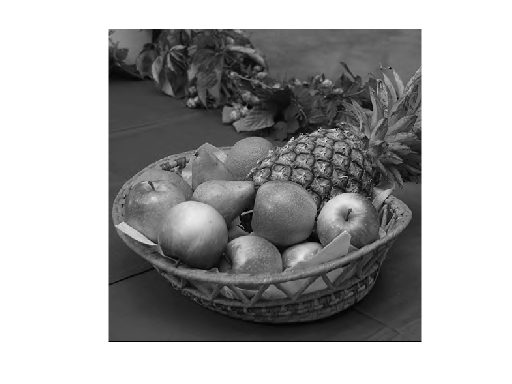


% Image to grayscale
RGB = img;
% Extract Red colour component to R, Green colour component to G 
% and Blue colour component to  B  
red=RGB(:, :, 1);
green=RGB(:, :, 2);
blue=RGB(:, :, 3);
% Getting number of rows in M and number of column in N of RGB image matrix 
% ~ is used to ignore dimension of RGB image
% as size(img) function will return row, column and dimension of the RGB image
[M, N, ~]=size(RGB);
 % creating a new 2-d matrix 'gray_img' of size M*N of 'uint8' data type with all 
 % elements  as zero 
 grayimage=zeros(M, N, 'uint8');
 % calculating grayscale values by forming a weighted sum of the R, G, and B components
 % for each pixel
 for i=1:M
     for j=1:N
           grayimage(i, j)=(R(i, j)*0.2)+(G(i, j)*0.7)+(B(i, j)*0.1);
     end
 end
figure('Name','Grayscaled Image','NumberTitle','off');
imshow(grayimage);

### Q1.1

Q: Compared with the original image (Figure 1), what have you generally observed from the brightness or intensity patterns in Figures 2, 3 and 4? 

The brighter/intense a certain part is in the color channel, the more that part's color in the original image is similar to the color of the channel is. Therefore, in the green channel, the bright/white areas in it will likely have the corresponding area in the original image to be also green. For example, the red channel generally has brighter/whiter shades on areas of the apple. That is because the areas of the apple are red. Meanwhile, for the blue channel, it generally has a darker shade because those areas are lacking in the color blue.

### Q1.2

Use the graph below in deciding the respective weights for the R, G, and B channels (then briefly explain your method). 

In order to convert the current image into a grayscale, the weights for the linear combination of the red, green, and blue must be determined. According to the graph, since the green cone is closest to the rod, the human eye is most sensitive to green, therefore giving it the most weight. The following cones that are closest are red, and then blue; therefore red would have the 2nd highest weight and blue would have the least weight.  Thus, (R*0.2 + G*0.7 + B*0.1). 

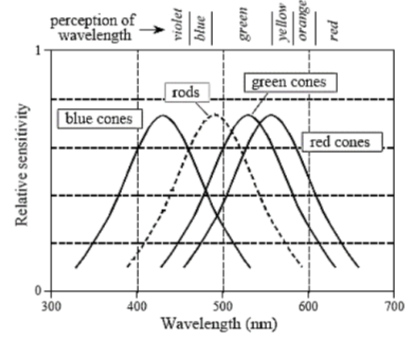

## Brightness and Contrast

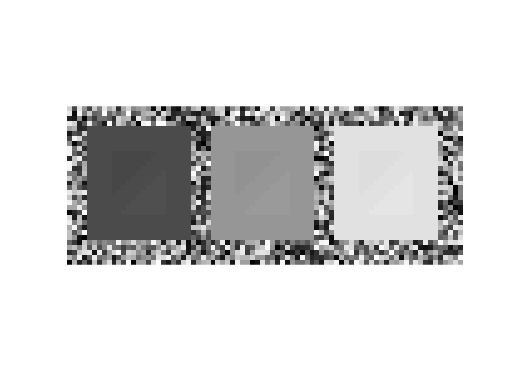

% Brightness and Contrast
% Draw Rectangle with Generated Noise
row = 32;
col = 80;
% testimage = zeros(row, col, 'uint8');
testimage = randi([0, 255],row, col, 'uint8');

% Draw Squares
for r=5:row-5
    for c=5:25
        testimage(r,c) = 75;
    end
    for c=30:50
        testimage(r,c) = 150;
    end
    for c=55:75
        testimage(r,c) = 225;
    end
end

% % Draw Squares inside Squares
% for r=10:row-10    
%     for c=5+5:25-5
%         testimage(r,c) = 255;
%     end
%     for c=30+5:50-5
%         testimage(r,c) = 255;
%     end
%     for c=55+5:75-5
%         testimage(r,c) = 255;
%     end
% end

% Draw Triangles inside Squares
gap = 2;
startrow = 10;
endrow = row-10;

startcol = 5+5;
endcol = 25-5;
for i=0:9
    for c=startcol:endcol-(gap+i)
        testimage(startrow+i,c) = 71;
    end
    for c=endcol:-1:startcol+(gap+i)
        testimage(endrow-i,c) = 79;
    end
end
startcol = 30+5;
endcol = 50-5;
for i=0:9
    for c=startcol:endcol-(gap+i)
        testimage(startrow+i,c) = 146;
    end
    for c=endcol:-1:startcol+(gap+i)
        testimage(endrow-i,c) = 154;
    end
end
startcol = 55+5;
endcol = 75-5;
for i=0:9
    for c=startcol:endcol-(gap+i)
        testimage(startrow+i,c) = 221;
    end
    for c=endcol:-1:startcol+(gap+i)
        testimage(endrow-i,c) = 229;
    end
end
figure('Name','Test Image','NumberTitle','off');
imshow(testimage);

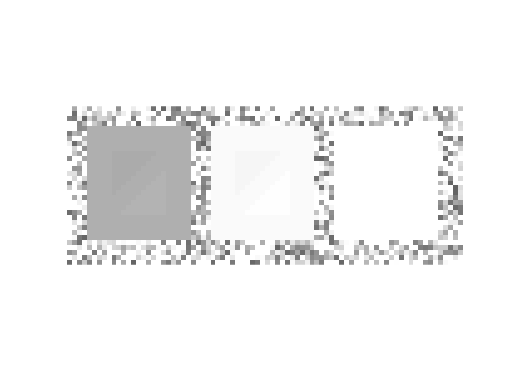


b100 = testimage + 100;
figure('Name','+100 Brightness Image','NumberTitle','off');
imshow(b100);

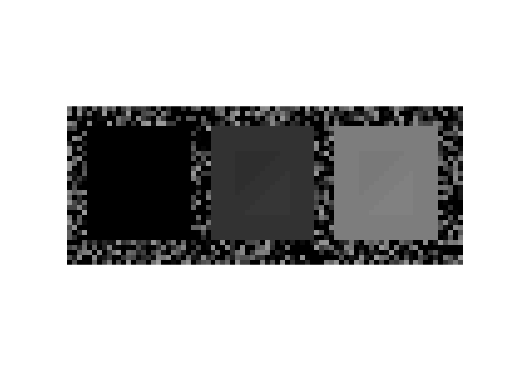


d100 = testimage - 100;
figure('Name','-100 Brightness (Darker) Image','NumberTitle','off');
imshow(d100);

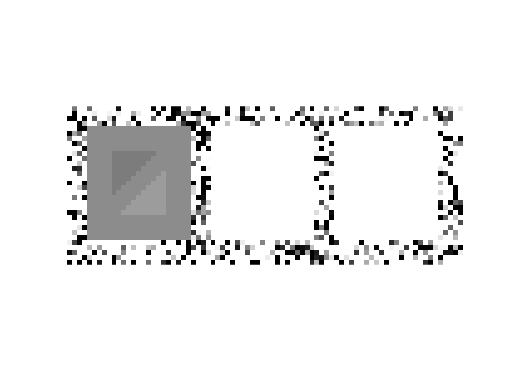


t1 = (testimage-40)*4;
figure('Name','T1 Image','NumberTitle','off');
imshow(t1);

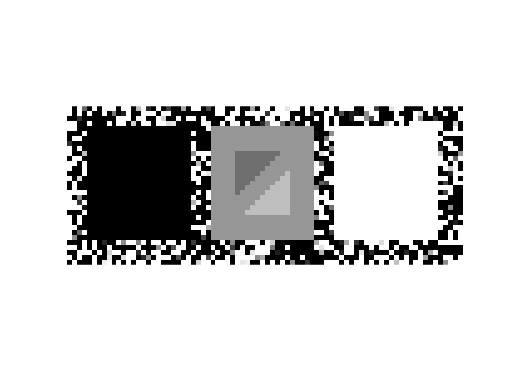


t2 = (testimage-135)*10;
figure('Name','T2 Image','NumberTitle','off');
imshow(t2);

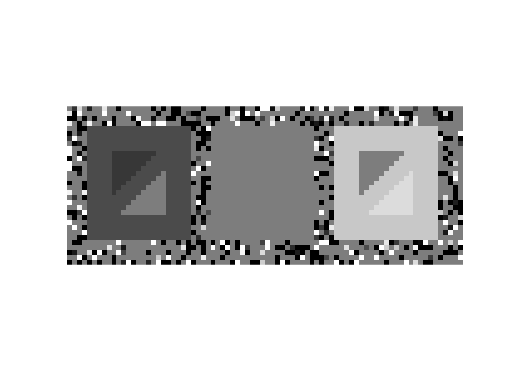


t3 = testimage;
[row, col] = size(t3);
for r=1:row
    for c=1:col
        if t3(r,c)<=75
            t3(r,c) = (t3(r,c)-60)*5;
        elseif t3(r,c)>75 && t3(r,c) <225
            t3(r,c) = 125;
        elseif t3(r,c)>=225
            t3(r,c) = (t3(r,c)-185)*5;
        end
    end
end
figure('Name','T3 Image','NumberTitle','off');
imshow(t3);

## Histogram Equalization

% METHOD 1

% read and display image
img = imread('ir_cam_im.bmp');
% imshow(img);

% PARAMETER: number of gray levels (typically 256), intensity range, scaling
L = 256;

% count the intensities
[row, col] = size(img);
count = zeros(256,1);
% the 1 represents intensity 0 [0~255]
for i=1:256
    for r=1:row
        for c=1:col
            if i-1 == img(r,c)
                count(i) = count(i) + 1;
            end
        end
    end 
end

% compute probabilities
totalelem = numel(img);
countprobs = zeros(size(count));
for i=1:length(count)
    countprobs(i) = count(i)/totalelem;
end

% compute cumulative probabilities
cumprobs = zeros(size(count));
cumprobs(1) = countprobs(1);
for i=2:length(count)
    cumprobs(i) = cumprobs(i-1)+countprobs(i);
end

% pixel scaling
l = L-1;
hepixels = zeros(size(count));
for i=1:length(count)
    hepixels(i) = cumprobs(i)*l;
end

% rounding down / floor
for i=1:length(hepixels)
    hepixels(i) = floor(hepixels(i));
end

% pixel mapping
histedimg1 = img;
for r=1:row
    for c=1:col
        pixelval = histedimg1(r,c);
        histedimg1(r,c) = hepixels(pixelval+1);
    end
end 

% % for COMPARING/TESTING with the actual histeq functions
% histequalized = histeq(img);
% [counts,binLocations] = imhist(img);

figure('Name','Histogram Equalization Images','NumberTitle','off');
subplot(1,2,1);
imshow(img);

title('Original Image');
subplot(1,2,2);
imshow(histedimg1);

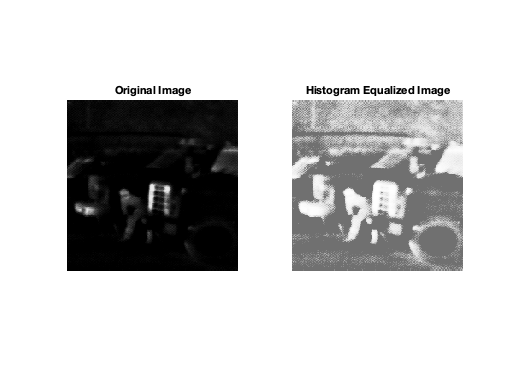

title('Histogram Equalized Image');

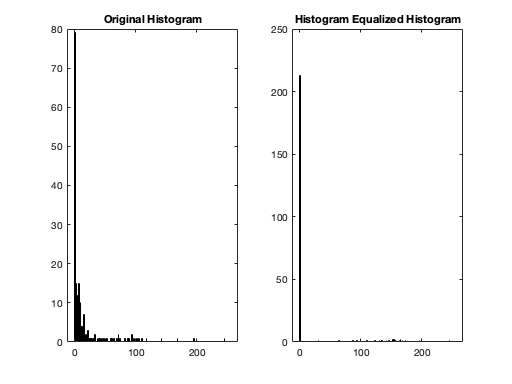


figure('Name','Histogram (Using histogram function)','NumberTitle','off');
binlocation = (0:255)';
histedcount = zeros(256,1);
for i=1:256
    for r=1:row
        for c=1:col
            if i-1 == histedimg1(r,c)
                histedcount(i) = histedcount(i) + 1;
            end
        end
    end 
end
subplot(1,2,1);
histogram(count,binlocation);
title('Original Histogram');
subplot(1,2,2);
histogram(histedcount,binlocation);
title('Histogram Equalized Histogram');

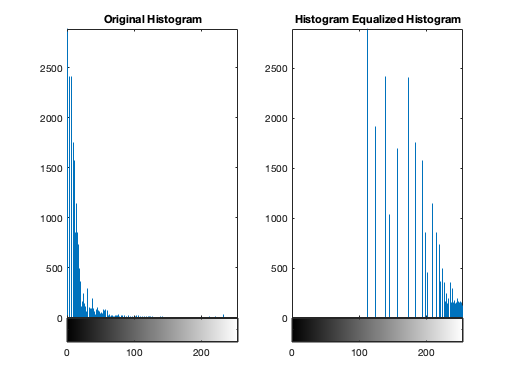



figure('Name','Histogram (Using imhist function)','NumberTitle','off');
subplot(1,2,1);
imhist(img);
title('Original Histogram');
subplot(1,2,2);
imhist(histedimg1);
title('Histogram Equalized Histogram');

% METHOD2

% read and display image
img = imread('ir_cam_im.bmp');
% imshow(img);

% PARAMETER: number of gray levels (typically 256), intensity range, scaling
L = 256;

% count the intensities
[row, col] = size(img);
count = zeros(256,1);
% the 1 represents intensity 0 [0~255]
for i=1:256
    for r=1:row
        for c=1:col
            if i-1 == img(r,c)
                count(i) = count(i) + 1;
            end
        end
    end 
end

% compute cumulative frequency
cumfreq = zeros(size(count));
cumfreq(1) = count(1);
for i=2:length(cumfreq)
    cumfreq(i) = cumfreq(i-1)+count(i);
end

% get mininum cumulative frequency
for i=1:length(count)
    if count(i) > 0
        cdfmin = i-1;
        break;
    end 
end

% map to scaled values
histedimg2 = img;
M = row;
N = col;
for r=1:row
    for c=1:col
        v = histedimg2(r,c)+1;
        h = floor((cumfreq(v) - cdfmin) / ((M*N) - cdfmin) * (L-1));
        histedimg2(r,c) = h;
    end
end 

% % for COMPARING/TESTING with the actual histeq functions
% histequalized = histeq(img);
% [counts,binLocations] = imhist(img);

figure('Name','Histogram Equalization Images','NumberTitle','off');
subplot(1,2,1);
imshow(img);

title('Original Image');
subplot(1,2,2);
imshow(histedimg2);

title('Histogram Equalized Image');


figure('Name','Histogram (Using histogram function)','NumberTitle','off');
binlocation = (0:255)';
histedcount = zeros(256,1);
for i=1:256
    for r=1:row
        for c=1:col
            if i-1 == histedimg2(r,c)
                histedcount(i) = histedcount(i) + 1;
            end
        end
    end 
end
subplot(1,2,1);
histogram(count,binlocation);
title('Original Histogram');
subplot(1,2,2);
histogram(histedcount,binlocation);
title('Histogram Equalized Histogram');



figure('Name','Histogram (Using imhist function)','NumberTitle','off');
subplot(1,2,1);
imhist(img);
title('Original Histogram');
subplot(1,2,2);
imhist(histedimg2);
title('Histogram Equalized Histogram');

### Thresholding and Binarization

% read and display image
img = imread('ir_cam_im.bmp');
% imshow(img);

% histogram equalization (method 2)
% PARAMETER: number of gray levels (typically 256), intensity range, scaling
L = 64;
% count the intensities
[row, col] = size(img);
count = zeros(256,1);
% the 1 represents intensity 0 [0~255]
for i=1:256
    for r=1:row
        for c=1:col
            if i-1 == img(r,c)
                count(i) = count(i) + 1;
            end
        end
    end 
end
% compute cumulative frequency
cumfreq = zeros(size(count));
cumfreq(1) = count(1);
for i=2:length(cumfreq)
    cumfreq(i) = cumfreq(i-1)+count(i);
end
% get mininum cumulative frequency
for i=1:length(count)
    if count(i) > 0
        cdfmin = i-1;
        break;
    end 
end
% map to scaled values
histedimg2 = img;
M = row;
N = col;
for r=1:row
    for c=1:col
        v = histedimg2(r,c)+1;
        h = floor((cumfreq(v) - cdfmin) / ((M*N) - cdfmin) * (L-1));
        histedimg2(r,c) = h;
    end
end 
binlocation = (0:255)';
histedcount = zeros(256,1);
for i=1:256
    for r=1:row
        for c=1:col
            if i-1 == histedimg2(r,c)
                histedcount(i) = histedcount(i) + 1;
            end
        end
    end 
end

% thersholding1: split the histogram into half based on cumulative frequency
totalfreq = 0;
half = sum(histedcount)/2;
for i=1:length(histedcount)
    totalfreq = totalfreq + histedcount(i);
    if totalfreq > half
        threshold1 = i;
        break;
    end
end
% binarization1
bin1img = img;
for r=1:row
    for c=1:col
        if bin1img(r,c) < threshold1
            bin1img(r,c) = 0;
        else
            bin1img(r,c) = 255;
        end
    end
end

% thersholding2: split the histogram based on the average between 2 peaks
[maxval, maxind] = max(histedcount);
[secval, secind] = max(histedcount(histedcount ~= maxval));
avemax = mean(maxind, secind);
threshold2 = avemax;
% binarization2
bin2img = img;
for r=1:row
    for c=1:col
        if bin2img(r,c) < threshold2
            bin2img(r,c) = 0;
        else
            bin2img(r,c) = 255;
        end
    end
end

figure('Name','Binarization Images','NumberTitle','off');
subplot(1,3,1);
imshow(img);

title('Original Image');
subplot(1,3,2);
imshow(bin1img);

title('Binarized(by Cumulative Frequency/2) Image');
subplot(1,3,3);
imshow(bin2img);

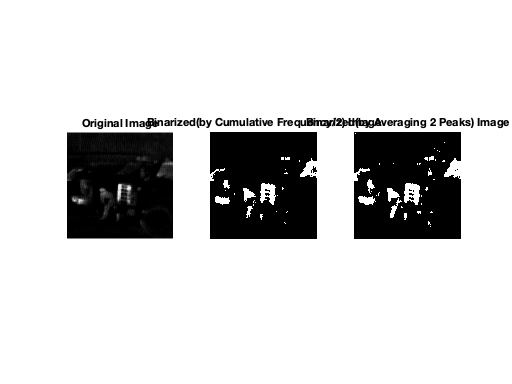

title('Binarized(by Averaging 2 Peaks) Image');

### Q3.1

Explain your main algorithm and discuss how you set parameters (if any). 

The only parameter that could be set is L which represents the total number of gray levels (which is usually 256). This also represents the desired intensity range (0~L-1) or the scaling factor. If I wanted an intensity range of 0 ~ 100 then the L would have the value of 101. Two algorithms were implemented. 

Based from this formula: 

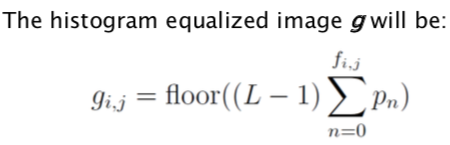

The algorithms is as follows: 

- Get frequency for each intensity 

- Get probability for each intensity 

- Frequency divided by Total Elements 

- Get cumulative probability for each intensity 

- Cumulative Probability = Cumulative Probability of the Previous Item + Current Item’s Probability 

- Unless if you’re the first item, then your cumulative probability is your own probability 

- Scale the cumulative probabilities by L 

- Cumulative Probability * (L-1) 

- Floor/Round down the values 

- Map each intensity to the corresponding scaled value. 

Based from this formula:

The algorithm is as follows: 

- Get frequency for each intensity 

- Get cumulative frequency for each intensity 

- Get minimum cumulative frequency 

- map each pixel according to the formula 

- h = floor((cumfreq(v) - cdfmin) / ((M*N) - cdfmin) * (L-1)); 

The 2 methods were then compared to one another with isequal(histedimg1, histedimg2), and shows that both images are equal proving the 2 methods to be of equal transformations. 

### Q3.2

Q: How did you set your threshold? (Discuss your answer) 

Both ways utilize the histogram equalization to spread the values more so that when cutting the values in half, the values are not biased to one side. The parameter for L, also known as total number of gray levels, was adjusted to be 64. This is because when the L was set to 256, it provided the same problem of being biased as more values are now biased towards the brighter end (255 values). The L value 64 was shown to result into a better outline of the human than 256, and 128. 

The thresholding was done in 2 ways. The first way involves cutting the histogram in half based on cumulative frequency. When the cumulative frequency exceeds half the total frequency, that index/part of the intensity is set as the threshold. The second way involves finding the 2 peak values of the histogram. Once the 2 peak values were identified, the average between the peaks were set as the threshold. Based from the resulting images, it can be stated that averaging between 2 peaks was the better threshold. 

## Geometric Transforms

## Image Translation

% read and display image
img = imread('L_shaped1.bmp');
% imshow(img);

bx = 95; % shift columns
by = 78; % shift rows

[row, col] = size(img);
trans = uint8(zeros(row, col));

for r=1:row
    for c=1:col
        x2 = r+bx;
        y2 = c+by;
        if x2 <= row && y2 <= col && x2 >= 1 && y2 >= 1
            trans(x2, y2) = img(r, c);
        end
    end
end

figure('Name','Translated Images (L1)','NumberTitle','off');
subplot(1,2,1);
imshow(img);

title('Original Image');
subplot(1,2,2);
imshow(trans);

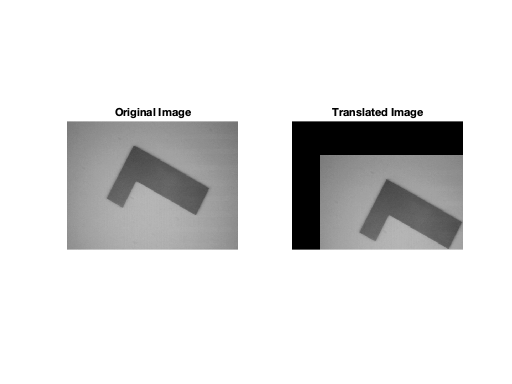

title('Translated Image');


% read and display image
img = imread('L_shaped2.bmp');
% imshow(img);

bx = 45; % shift columns
by = 65; % shift rows

[row, col] = size(img);
trans = uint8(zeros(row, col));

for r=1:row
    for c=1:col
        x2 = r+bx;
        y2 = c+by;
        if x2 <= row && y2 <= col && x2 >= 1 && y2 >= 1
            trans(x2, y2) = img(r, c);
        end
    end
end

figure('Name','Translated Images (L2)','NumberTitle','off');
subplot(1,2,1);
imshow(img);

title('Original Image');
subplot(1,2,2);
imshow(trans);

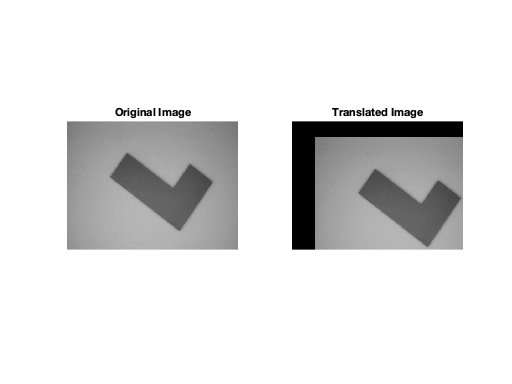

title('Translated Image');

## Q4.1

Q: What are the values of your βx and βy for each test image case? How did you obtain these values? Explain briefly. 

Based the implementation on the formula: 

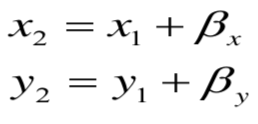

(For 'L_shaped1.bmp') 

Bx = 95. By = 78. Positive values translate the image towards the right downwards. So both values were positive. Values were obtained by trial and error. 100 is too much and 80 was also too much but both were too much by a little, so when reduced by a little, it fit perfectly. 

(For 'L_shaped2.bmp’) 

Bx = 45 By = 65. Found through trial and error. 

## Image Rotation

% read and display image
img = imread('L_shaped1.bmp');
% imshow(img);

[row, col] = size(img);
rot1 = uint8(zeros(row, col));
rot2 = uint8(zeros(row, col));
% get center points
cx = floor(row/2);
cy = floor(col/2);

theta1 = 90;
theta2 = 90*-1;

% Method 1
theta = theta1;
for r=1:row
    for c=1:col
        x2 = round(cos(theta) * (r-cx) - sin(theta) * (c-cy) + cx);
        y2 = round(sin(theta) * (r-cx) + cos(theta) * (c-cy) + cy);
        if x2 <= row && y2 <= col && x2 >= 1 && y2 >= 1
            rot1(x2,y2) = img(r, c);
        end
    end
end

% Method 2
theta = theta2;
for r=1:row
    for c=1:col
        x2 = round(cos(theta) * (r-cx) - sin(theta) * (c-cy) + cx);
        y2 = round(sin(theta) * (r-cx) + cos(theta) * (c-cy) + cy);
        if x2 <= row && y2 <= col && x2 >= 1 && y2 >= 1
            rot2(r,c) = img(x2, y2);
        end
    end
end

% figure('Name','Rotated Images (L1)','NumberTitle','off');
% subplot(1,3,1);
% imshow(img);
% title('Original Image');
% subplot(1,3,2);
% imshow(rot1);
% title('Rotated Image (M1)');
% subplot(1,3,3);
% imshow(rot2);
% title('Rotated Image (M2)');

img = imread('L_shaped2.bmp');
% imshow(img);
% get center points
cx = floor(row/2);
cy = floor(col/2);

theta1 = 17.9;
theta2 = 17.9*-1;
% Method 1
theta = theta1;
for r=1:row
    for c=1:col
        x2 = round(cos(theta) * (r-cx) - sin(theta) * (c-cy) + cx);
        y2 = round(sin(theta) * (r-cx) + cos(theta) * (c-cy) + cy);
        if x2 <= row && y2 <= col && x2 >= 1 && y2 >= 1
            rot1(x2,y2) = img(r, c);
        end
    end
end
% Method 2
theta = theta2;
for r=1:row
    for c=1:col
        x2 = round(cos(theta) * (r-cx) - sin(theta) * (c-cy) + cx);
        y2 = round(sin(theta) * (r-cx) + cos(theta) * (c-cy) + cy);
        if x2 <= row && y2 <= col && x2 >= 1 && y2 >= 1
            rot2(r,c) = img(x2, y2);
        end
    end
end
figure('Name','Rotated Images (L2)','NumberTitle','off');
subplot(1,3,1);
imshow(img);

title('Original Image');
subplot(1,3,2);
imshow(rot1);

title('Rotated Image (M1)');
subplot(1,3,3);
imshow(rot2);

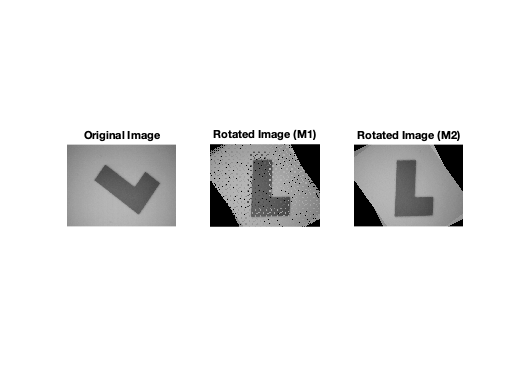

title('Rotated Image (M2)');

### Q4.2 

Q: What are the values of your θ and (x0, y0) for each test image case? How did you obtain these values? Explain briefly. 

Implementation was based off the formula: 

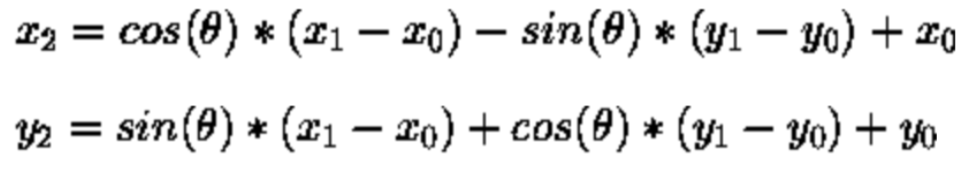

2 methods was implemented that observes the above formula. Implementing the formula above as it is results into an image that has holes in it also known as aliasing. By modifying the first method, the second method removes the problem of aliasing but instead requires to adjust its initial values. For example, if an image was rotated with theta as 90, then for the second method to have the same rotation as the first method, theta must be multiplied by -1 resulting into -90.  

First method has theta 90. Second method has theta -90. For same result of rotated image. 

The x0 and y0 values was selected to match the center of the image as that would capture the most amount of pixels in the resulting image. Rotating on the corner might lead to only a small part of the image remaining in the rotated image. Thus, with the image dimension of 360 by 480 the values are x0 = 180 and y0 = 240. 

(For 'L_shaped1.bmp') 

For the theta value, the initial tested value of theta = 90 worked out in resulting in a L shaped image. 

(For 'L_shaped2.bmp’) 

For the theta value, multiple testing was done, after trial and error the found value is theta = 17.9 for a L shaped image. Testing started from theta = 10 and incremented the value by 5 for each test image. theta = 20 was close so with a little more testing 18 and 17.9 was found to have the desired image. 

## Size Difference Estimation

% read and display image
L1 = imread('L_shaped1.bmp');
L2 = imread('L_shaped2.bmp');

% COUNT FOR L1

% histogram equalization to spread out the values
img = L1;
L = 128;
% count the intensities
[row, col] = size(img);
count = zeros(256,1);
% the 1 represents intensity 0 [0~255]
for i=1:256
    for r=1:row
        for c=1:col
            if i-1 == img(r,c)
                count(i) = count(i) + 1;
            end
        end
    end 
end
% compute cumulative frequency
cumfreq = zeros(size(count));
cumfreq(1) = count(1);
for i=2:length(cumfreq)
    cumfreq(i) = cumfreq(i-1)+count(i);
end
% get mininum cumulative frequency
for i=1:length(count)
    if count(i) > 0
        cdfmin = i-1;
        break;
    end 
end
% map to scaled values
histedimg2 = img;
M = row;
N = col;
for r=1:row
    for c=1:col
        v = histedimg2(r,c)+1;
        h = floor((cumfreq(v) - cdfmin) / ((M*N) - cdfmin) * (L-1));
        histedimg2(r,c) = h;
    end
end
binlocation = (0:255)';
histedcount = zeros(256,1);
for i=1:256
    for r=1:row
        for c=1:col
            if i-1 == histedimg2(r,c)
                histedcount(i) = histedcount(i) + 1;
            end
        end
    end 
end
% thresholding to cut the values into the L shape and the background
% thersholding2: split the histogram based on the average between 2 peaks
[maxval, maxind] = max(histedcount);
[secval, secind] = max(histedcount(histedcount ~= maxval));
avemax = mean(maxind, secind);
threshold2 = avemax;
% binarization2
bin2img = img;
for r=1:row
    for c=1:col
        if bin2img(r,c) < threshold2
            bin2img(r,c) = 0;
        else
            bin2img(r,c) = 255;
        end
    end
end

% count the white parts aka the L shaped values
countforL1 = 0;
for r=1:row
    for c=1:col
        if bin2img(r,c) == 255
            countforL1 = countforL1+1;
        end
    end
end

% COUNT FOR L2

% histogram equalization to spread out the values
img = L2;
% count the intensities
[row, col] = size(img);
count = zeros(256,1);
% the 1 represents intensity 0 [0~255]
for i=1:256
    for r=1:row
        for c=1:col
            if i-1 == img(r,c)
                count(i) = count(i) + 1;
            end
        end
    end 
end
% compute cumulative frequency
cumfreq = zeros(size(count));
cumfreq(1) = count(1);
for i=2:length(cumfreq)
    cumfreq(i) = cumfreq(i-1)+count(i);
end
% get mininum cumulative frequency
for i=1:length(count)
    if count(i) > 0
        cdfmin = i-1;
        break;
    end 
end
% map to scaled values
histedimg2 = img;
M = row;
N = col;
for r=1:row
    for c=1:col
        v = histedimg2(r,c)+1;
        h = floor((cumfreq(v) - cdfmin) / ((M*N) - cdfmin) * (L-1));
        histedimg2(r,c) = h;
    end
end
binlocation = (0:255)';
histedcount = zeros(256,1);
for i=1:256
    for r=1:row
        for c=1:col
            if i-1 == histedimg2(r,c)
                histedcount(i) = histedcount(i) + 1;
            end
        end
    end 
end
% thresholding to cut the values into the L shape and the background
% thersholding2: split the histogram based on the average between 2 peaks
[maxval, maxind] = max(histedcount);
[secval, secind] = max(histedcount(histedcount ~= maxval));
avemax = mean(maxind, secind);
threshold2 = avemax;
% binarization2
bin2img = img;
for r=1:row
    for c=1:col
        if bin2img(r,c) < threshold2
            bin2img(r,c) = 0;
        else
            bin2img(r,c) = 255;
        end
    end
end

% count the white parts aka the L shaped values
countforL2 = 0;
for r=1:row
    for c=1:col
        if bin2img(r,c) == 255
            countforL2 = countforL2+1;
        end
    end
end

% isequal(L1, L2)
% isequal(countforL1, countforL2)
% countforL1
% countforL2
% countforL2 - countforL1

## Q4.3 

Using a combination of histogram equalization, thresholding (and possibly rotation and translation), write a script that determines the approximate difference in size (in terms of number of pixels) of the two L-shaped objects. Briefly explain your algorithm. 

Based from the general view of the 2 images, it can be inferred that the L-shaped object is composed of lighter shades of intensity compared to the background. This leads to the solution that if the L-shaped object and the background was separated, then counting the pixels of the L-shape would be easier. 

The algorithm is as follows: 

- To separate the L-shape object from the background 

- Histogram Equalization 

- Thresholding based off the average of the 2 peaks of the histogram 

- Binarization 

- L-shaped pixels = 255 

- Background = 0 

- Count the L-shaped pixels 

### Results

When the L value for the histogram equalization is L = 64 then the counted values for the L1-shaped object and the L2-shaped object are equal. The counted values for L1 and L2 are 172800 pixels. But when the L value is changed to L = 128, comes a difference between the 2 L-shaped objects. The counted pixel values are L1 = 161,085 and L2 = 163,690. The estimated difference is 2605 pixels making the L2 object larger than the L1 object. 

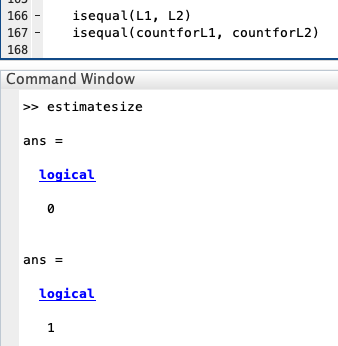    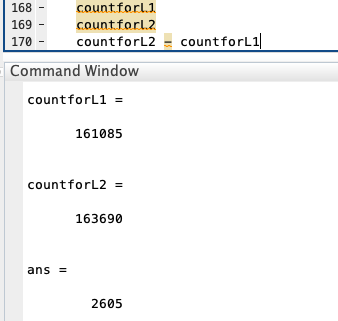

By doing some rotations, it can be observed that the L2 object is indeed bigger than the L1 object. By setting the L value to be higher (but not too high), the contrast between the L-object and the background is better outlined. (Left image is L1 and Right image is L2)

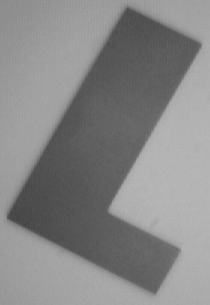  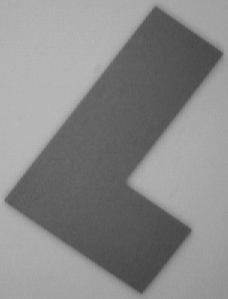

The conclusion is that by setting the L value differently (and hopefully correctly), the estimated pixel difference between the 2 L-shaped objects can be derived. 